# Sliding mode control

- Simple example (https://www.youtube.com/watch?v=_NTMkXdbX6o) 

Consider 

           ${\dot{x} }_1 =x_{2\;} ,{\dot{\;x} }_2 =u+f\;,\;f:\textrm{unknown}\;\textrm{disturbance}$,  (1)

Design $u$ the trajectories converge to zero 

1. Without disturbace 

             
$$u=-k_1 x_1 -k_{2\;} x_{2\;}$$


2. With Disturbance ,$f=\textrm{sin2t}\;$, the trajectories do not converge to zero

3. Sliding mode control. 

  1)** sliding phase**:  Define sliding manifold (as you wish) as

          
$$s={\textrm{cx}}_{1\;} +{\dot{x\;} }_1 ,c:\textrm{design}\;\textrm{variable}$$


  If the trajectories enter this manifold, we want it will stay in this manifold, hence

        
$$0={\textrm{cx}}_{1\;} +{\dot{x\;} }_1 \;\;-\to \;$$

$$x_1 =x_{10\;} e^{-\textrm{ct}}$$


 which implies if $\;\;\exists \;t_1 \;\;\left(x_1 \left(t_1 \right),x_{2\;} \left(t_2 \right)\right)\in \;s,\;s={\textrm{cx}}_1 +{\dot{x\;} }_1 ={\textrm{cx}}_{1\;} +x_2 ,\;\;$

     
$${\left(x_{1\;} \left(t\right),x_2 \left(t\right)\right)\;\in \;s\;,\;\forall \;t\;\ge \;t}_1$$
   

  2) **reaching phase**

    Control objective is $\forall \;\;\left(x_1 ,x_2 \right)\;,\textrm{design}\;\textrm{control}\;$$u$ such that $\left(x_{\textrm{c1}} ,x_{\textrm{c2}} \right)\;$reaches the sliding manifold evenif there is a disturbance. 

One method is to select a Lyapunov function $V\left(s\right)>0,\dot{\;V\;} \left(s\right)<0$. 

Select  $V\left(s\right)=\frac{1}{2\;}s^2$, then 

             
$$\dot{V\;} \left(s\right)=s\dot{s} =s\left(\;\dot{\;cx_1 \;} +\dot{\;x_2 } \right)=s\left({\textrm{cx}}_2 +u+f\right)$$


For $\dot{\;V}$ to be negative, select  $u=-{\textrm{cx}}_2 +\kappa \;$, then

        
$$\dot{V\;} \left(s\right)=s\dot{s} =s\left(\;\dot{\;cx_1 \;} +\dot{\;x_2 } \right)=s\left({\textrm{cx}}_2 +u+f\right)=s\left(\kappa +f\right)$$


If $\max \;\left|f\right|\;=L$ ,

      
$$\dot{V\;} \left(s\right)=s\dot{s} =s\left(\kappa +f\right)\le s\left(\kappa +L\right)$$


 $\kappa \;$is selected as $\rho >L\;$

 
$$-\rho \;\textrm{sign}\left(s\right)=\left\lbrace \begin{array}{cc}
-\rho \; & s>0\\
\rho \; & s<0
\end{array}\right.$$
   

so that 

       
$$\dot{V\;} \left(s\right)=s\dot{s} \le s\left(\kappa +L\right)\le -a\left|s\right|\;\;,\;a>\;0,\forall \;s\;$$


which is always negative 

3) In conclusion, (1) when $\max \;\left|f\right|=\;L$

    
$$u=-{\textrm{cx}}_2 -\rho \textrm{sign}\left(s\right)={\textrm{cx}}_{2\;} -\rho \;\textrm{sign}\left(x_1 +x_2 \right)$$


4) simulation

 Consier


$$\dot{\;x} {\;}_{1\;} =x_2$$



$$\dot{\;x} {\;}_2 =\;$$


  Here I  selected the time step = 0.001. 

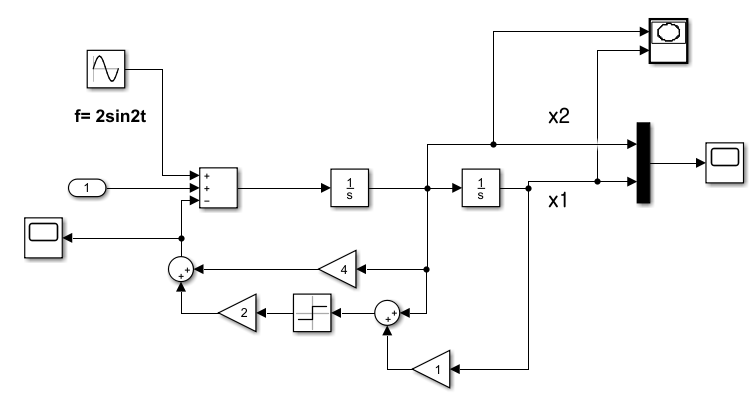

 Here $\left(x_1 \left(0\right),x_{2\;} \left(0\right)\right)=\left(1,1\right)$, the trajectory reaches the sliding manifold and converges to the origin evenif there is a disturbance as $2\textrm{sin2t}$. In the $\left(x,y\right)$ plane , there are two phases, reaching and sliding phases.

       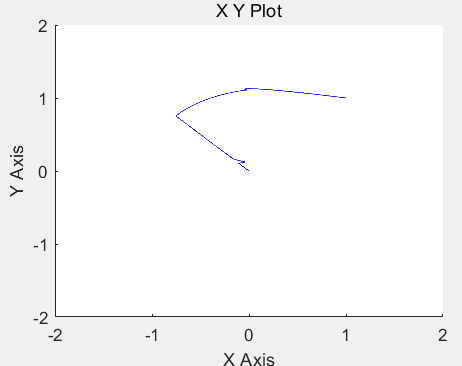 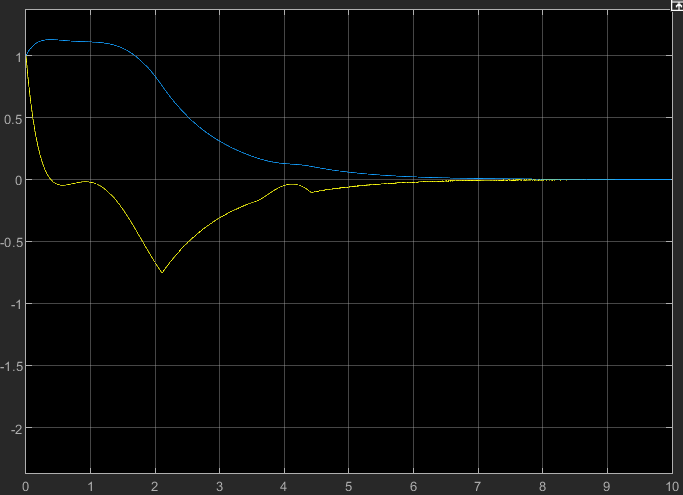

  Looks good. However in the sliding mode, increase the scale of the y-axis

                  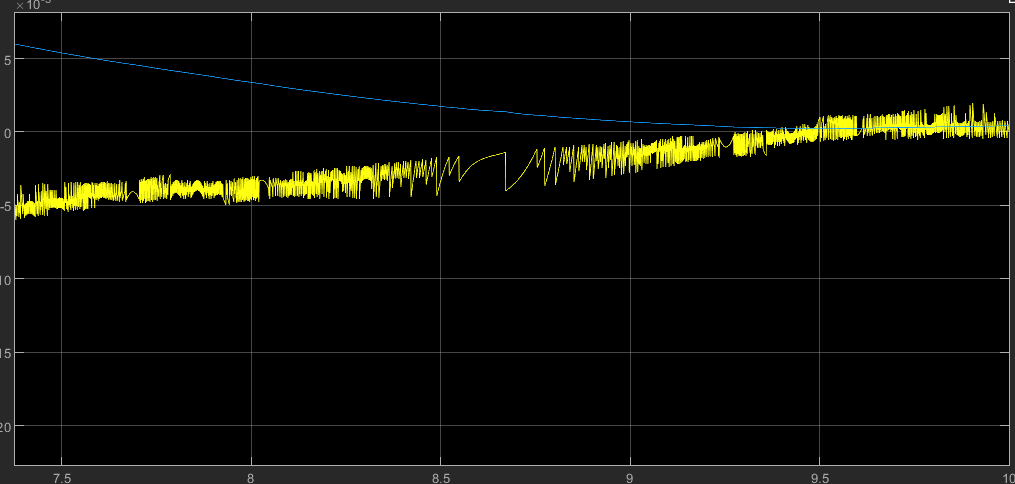

 there are high frequency vibrations, we call this as "chattering". Moreover the control input is 

                  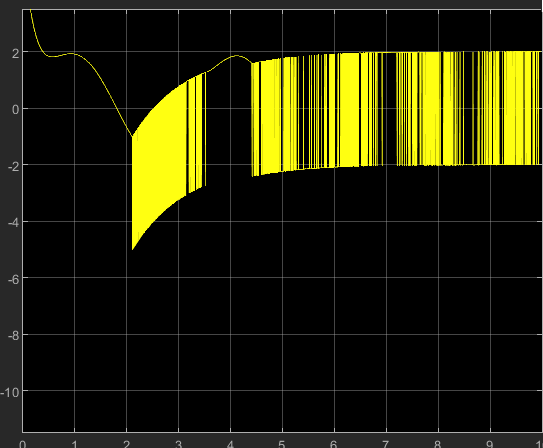

 also high frequncy vibration contained. 

   5) analyis

     The merits of sliding control is with unknown disturbance, but the maximum magnitude is known, simple to design a controller for convergence to the origin. 

    The demerits is "chattering" and control is very irregular of high frequencies. Hence the slidin mode control is not good to apply mechnical systems, especially geared system. 

  To remedy or attenuate the high frequency, there are several ways

     - use low pass filter for control input 

     - linear with a saturation 

  will be used. If you replace the sign function with a saturation, it may reduce the vibration. 

- Comment:  Slinding manifold in Linear system

Consider 

            
$$\dot{\;x} =\textrm{Ax}\;\;,x\in R^{2\;}$$


The eigenvector of $A$ are real , 

            
$${\textrm{Av}}_1 =\lambda_1 v_1 ,\;{\textrm{Av}}_{2\;} =\lambda_2 v_{2\;}$$


If the initial point $x\left(0\right)={\textrm{av}}_{1\;} ,$ then

                
$$x\left(t+\textrm{dt}\right)-x\left(t\right)=\textrm{Ax}\left(t\right)\textrm{dt}$$


-->   $x\left(\textrm{dt}\right)=\textrm{Ax}\left(0\right)+x\left(0\right)=\left(a\lambda_1 +a\right)x\left(0\right)\;\;$

-->   $x\left(t\right)={\textrm{cv}}_1 \;\;\;\;\forall \;t\ge 0$

-->   $v_1 \;$eigenvector is an sliding manifold.

- Lyapunov function re-visited

consider a stable system

               
$$\dot{\;x} =f\left(x\right)$$


Assume $V\left(x\right)\;>0,\;V\left(0\right)=0,\;\dot{\;\;V} <0$, implies

              
$$V\left(x\left(t\right)\right)\;\;\le V\left(x\left(0\right)\right)$$


imples $V\left(x\right)\;-\to V\left(0\right)=0$

Now define a manifold $s=T\left(x\right),\;T^{-1\;} \;\textrm{exists}-\to V\left(s\right)>0,$ if $\dot{V} \left(s\right)<0$

  --> $V\left(s\left(t\right)\right)<V\left(s\left(0\right)\right)$

  --> $V\left(s\left(t\right)\right)-\to V\left(s=0\right)$

  We may call $s\left(t\right)\;$to be a sliding curve. 

- Difference between state linearization/backstepping and sliding mode control

In the backstepping the systme is 

                   
$$\dot{x} =f\left(x,u\right)\;$$


here, the model is known perfectly. However  in the sliding model 

                  
$$\dot{x} =f\left(x,u\right)+g\left(x\right)\;\;,\;\left|g\left(x\right)\right|\le L$$


here $g\left(x\right)\;$ is unknown but the maximum is estimated. In this case, there is no way to cancle 

the unknown function, it is impossible to apply the state linearization including backstepping.

In this concept, in our textbook , sliding control is a robust controller. 

If the non-linearity $g\left(x\right)$ is in the sector $\left\lbrack \alpha \;\;\beta \;\right\rbrack$, luckily, if the plant is linear, the circle criterior is possible even if the $g\left(x\right)$ is unknown. 

# Linear System Observer

- Problem : Consider a linear system 

                   
$$\dot{x} =\textrm{Ax}+\textrm{Bu},y=\textrm{Cx}$$


             Given $y$, find the state $x$  

         2. Kalman's observer (or any optimal  observer should be as)

              Define $\bar{x} =\textrm{observer}\;\textrm{of}\;x$. The observer dynamics is 

                                
$$\dot{\;\hat{x\;} } =A\hat{x} +\textrm{Bu}+H\left(y-C\hat{x\;} \right)=\left(A-\textrm{HC}\right)\hat{x} +\textrm{Bu}+\textrm{Hy}$$


              Define the error $e=x-\hat{x\;}$. Then 

                                   
$$\dot{e\;} =\left(A-\textrm{HC}\right)e$$


              To select the observer gain, it is better to converge faster than the plant, as a rule of thumb, it's eigenvalues are larger than 10 times of the that of the plant 

            3. Total system with observer is 

                     
$$\dot{x} =\textrm{Ax}+\textrm{Bu},y=\textrm{Cx}$$


                    
$$\dot{\;\hat{x\;} } =A\hat{x} +\textrm{Bu}+H\left(y-C\hat{x\;} \right)=\left(A-\textrm{HC}\right)\hat{x} +\textrm{Bu}+\textrm{Hy}$$


                         
$$=\left(A-\textrm{HC}\right)\hat{x\;\;} +\left\lbrack \begin{array}{cc}
B & H
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack$$


               and the output ob the observer is full states so that 

                      
$$\hat{y} \;=\textrm{Ix}$$


            4. Example in simulink 

                4.1 System

                       
$$\left\lbrack \begin{array}{c}
\dot{\;x_1 } \\
\dot{\;x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-2 & -3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack u,\;\;y=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


                 4.2 Observer                        

                      
$$\;\left\lbrack \begin{array}{c}
\dot{\hat{\;x_1 } } \\
\dot{\hat{\;x{\;}_2 } \;} 
\end{array}\right\rbrack =\left(\left\lbrack \begin{array}{cc}
0 & 1\\
-2 & -3
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
h_1 \\
h_{2\;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
\hat{x{\;}_1 } \\
\hat{x{\;}_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & h_1 \\
1 & h_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack \;$$


                         
$$\hat{y} =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{x{\;}_1 } \\
\hat{x{\;}_2 } 
\end{array}\right\rbrack$$


                     The initial values are

clear variables
A =[0 1; -2 -3];
B = [0;1];
C =[1 0];
eig(A)

ans =     -1
    -2


H = acker(A',C',[-10, -20])';
Aobs =A -H*C;
Bobs =[B H];
Cobs = eye(2,2);

Now in simulink  with initial value of the observer is $\left(\hat{x{\;}_1 } \left(0\right)\;,\hat{x{\;}_2 } \left(0\right)\right)=\left(1,-1\right)$

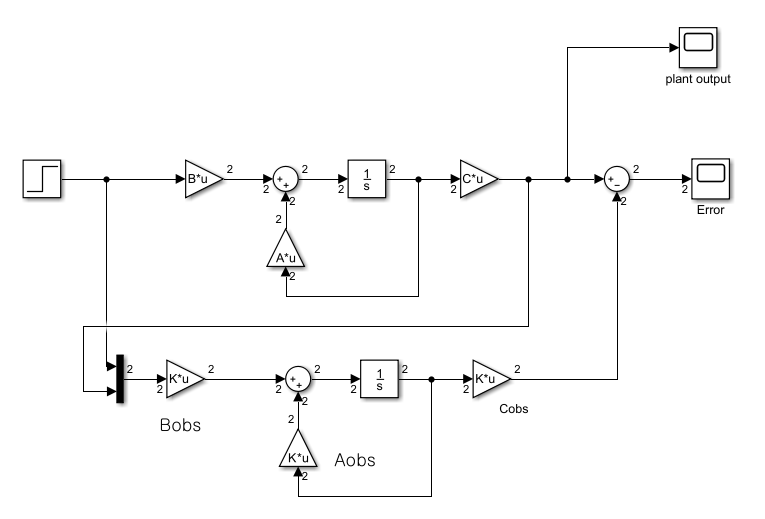

(Here there are numbers on the output signals, which indicates the number of signals. Click other dispalys - Signals and Ports - Signal Dimensions) . Then 

 The error between the plant and the observer outputs are 

   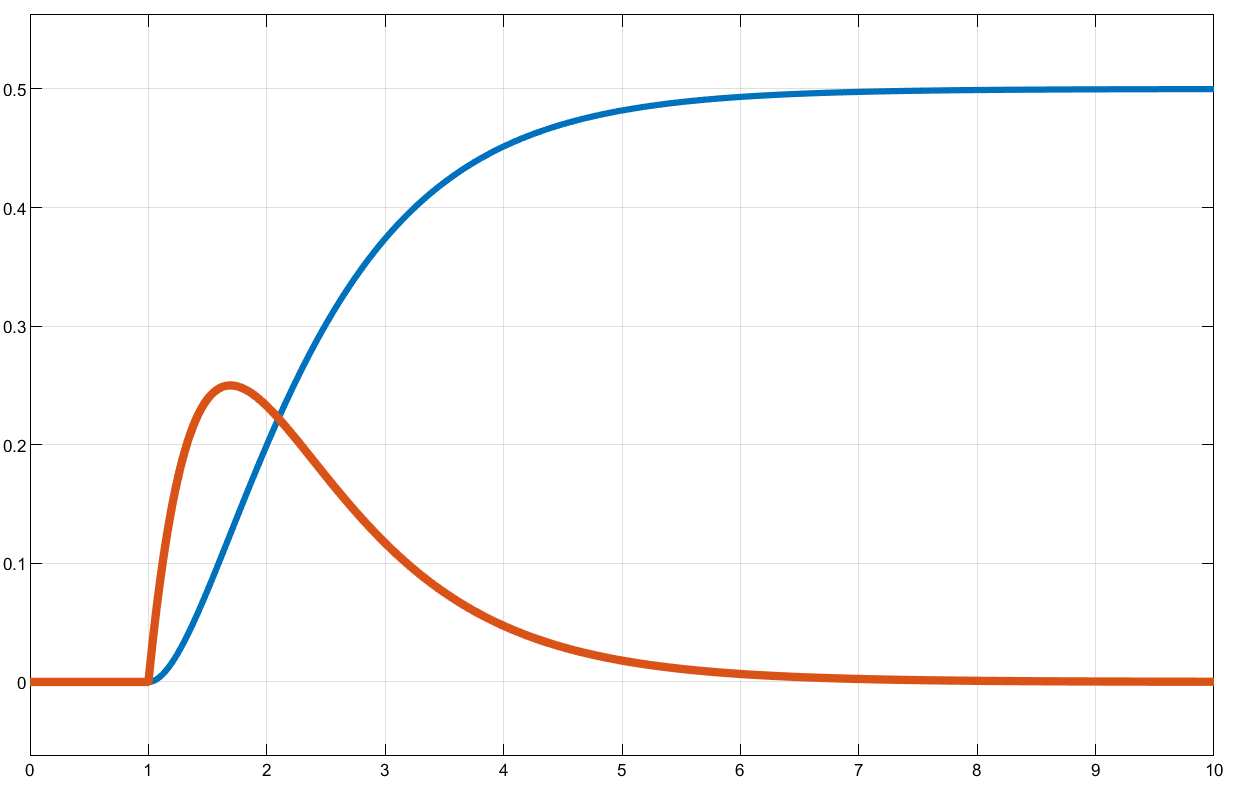          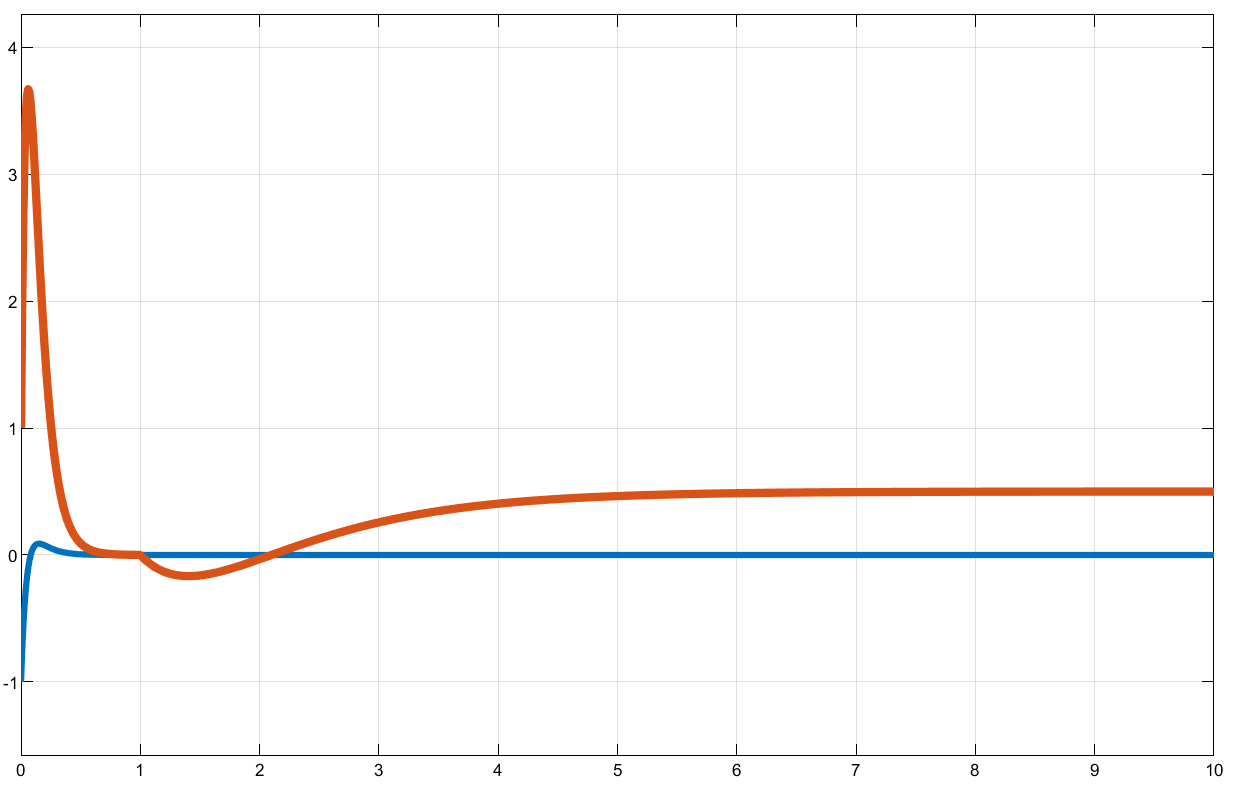        

In the first graph, the states of the plant are displayed, the blue is the  $x_1$ which is observed, the yellow is the  $x_{2\;}$ which is unoberved.   In the second graph, the blue is the error of $x_1 -\hat{x\;} {\;}_1$

    5. discussion abot the simulink environment

- You may change the simulation time step (here 0.001). Then the output is a little bit different due to Nyquist sampling rate.

-Here there are numbers on the output signals, which indicates the number of signals. Click other dispalys - Signals and Ports - Signal Dimensions 

#  Non-linear observer 

(The Extended Kalman Folter)

Consifder 

                                                           
$$\dot{\;x} =f\left(\left.x,u\right),y=h\left(x\right)\right)$$


The observer form

                                                        
$$\dot{\hat{x\;} } =f\left(\hat{x} \;,u\right)-H\left(t\right)\left(y-h\left(\hat{x\;} \right)\right)$$


The estination error $\tilde{x} =x-\hat{x\;}$ satisfies 

                                                    
$$\dot{\tilde{x\;} } =f\left(x,u\right)-f\left(\hat{x} \;,u\right)+H\left(h\left(x\right)-h\left(\tilde{x\;} \right)\right)\;$$


Then by Taylor series, 

                                                      
$$\dot{\tilde{x\;} } =\left(A-\textrm{HC}\right)\tilde{x} +\Delta \left(\tilde{x\;} ,x,u\right)\;\;\;\;\;\;\;\;\left(11\ldotp 9\right)$$


where

                                            
$$A=\frac{\partial f\left(x,u\right)\;}{\partial x},C=\frac{\partial f\;\;}{\partial x}$$


- Kalmna filter design 

-Observer gain: $H$

                                                        $H={\textrm{PC}}^{T\;} R^{-1\;}$                         (11.11)

where

                          
$$\dot{P\;} =\textrm{AP}+{\textrm{PA}}^{T\;} +Q-{\textrm{PC}}^{T\;} R^{-1\;} \textrm{CP},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;P\left(t_0 \right)=P_0$$


Under certain conditions,  the origin of the solution to (11.9) is** locally** asympt.stable with the observer gain (11.11).

- Ex.11.1

                 
$$\dot{x\;} =A_{1\;} x+B_{1\;} \;\left(0\ldotp 25\;x_1^{2\;} x_2 +0\ldotp 2\;\textrm{sint}\;t\right),\;y=\textrm{Cx}$$


1) estiamtion of the region of the attraction 

              
$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & -2
\end{array}\right\rbrack ,\;B_1 =\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \;,C_1 =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack$$


             Using a candidate Lyapunov function $V_1 =\frac{1}{2}x^{T\;} \left\lbrack \begin{array}{cc}
3 & 1\\
-1 & -2\;
\end{array}\right\rbrack x$, which is the solution of 

                                      
$$A^T P_1 +P_1 A=-I$$


              Using this, estimate the region of attraction of the original non-linear system, so that the domain of attraction $\Omega_c =\left\lbrace x:\left\|x\right\|\le 0\ldotp 8081\right\rbrace \;$(see the text book, p.281).

2) Riccati equation 

The original plant is

          
$$\dot{x\;} =A_{1\;} x+B_{1\;} \;\left(0\ldotp 25\;x_1^{2\;} x_2 +0\ldotp 2\;\textrm{sint}\;t\right),\;y=\textrm{Cx}$$


 which is rewrite as

      
$$\left\lbrack \begin{array}{c}
\dot{\;{\hat{\;x} }_1 } \\
\dot{\;{\hat{x} }_2 } 
\end{array}\right\rbrack =A\hat{x\;} +C\hat{x\;} =\left\lbrack \begin{array}{cc}
0 & 1\\
-1+0\ldotp 5\hat{\;x_1 } \hat{\;x_2 }  & -2-0\ldotp 25{\hat{x_1 } }^{2\;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{x_1 } \\
\hat{x_2 \;} 
\end{array}\right\rbrack \;+\left\lbrack 1\;0\right\rbrack \left\lbrack \begin{array}{c}
\hat{x_1 } \\
\hat{x_2 \;} 
\end{array}\right\rbrack$$
 

Define the solution to the Riccati equation as $P=\left\lbrack \begin{array}{cc}
p_{11}  & p_{12} \\
p_{12}  & p_{22} 
\end{array}\right\rbrack$ , 

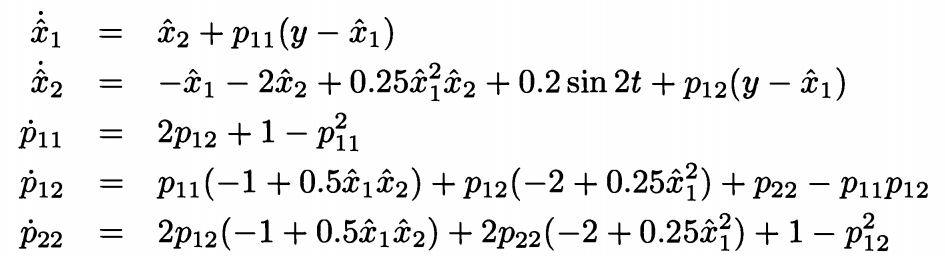

Here  $-2+0\ldotp 25\;\hat{x_2 \;} \;\;$ should be changed to $-2-0\ldotp 25\;\hat{x_2 \;} \;\;$

3) simulation in simulink

with the initial point $\left(x_{10} \;,x_{20} \right)=\left(1,-1\right)$ which is outside the region of attraction, 

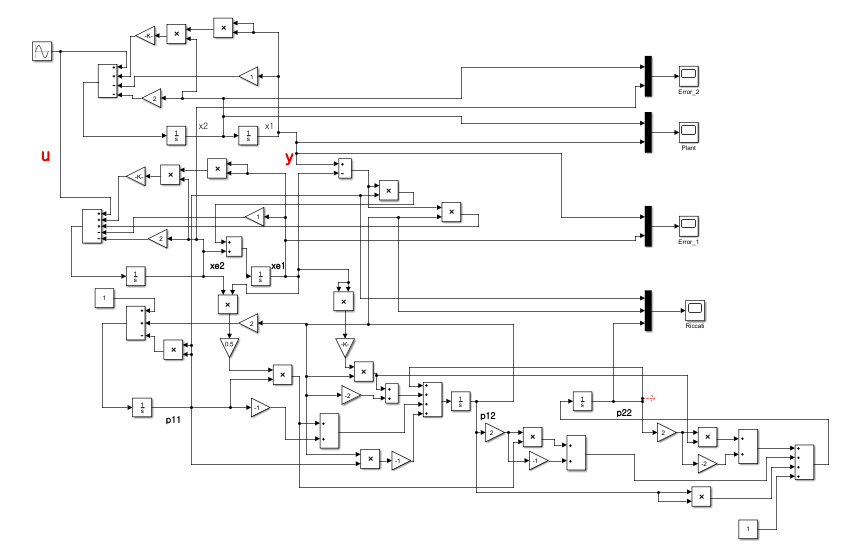

  4) output

      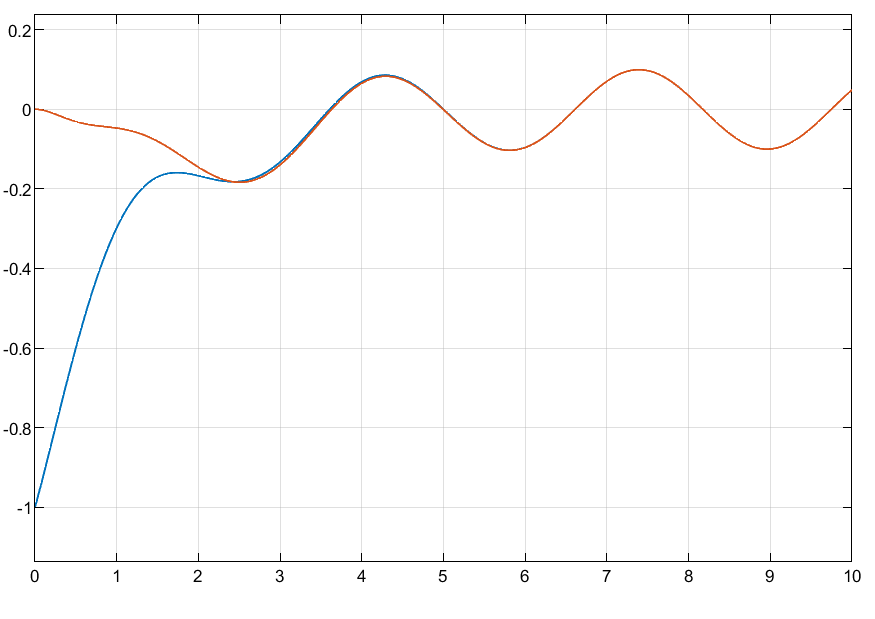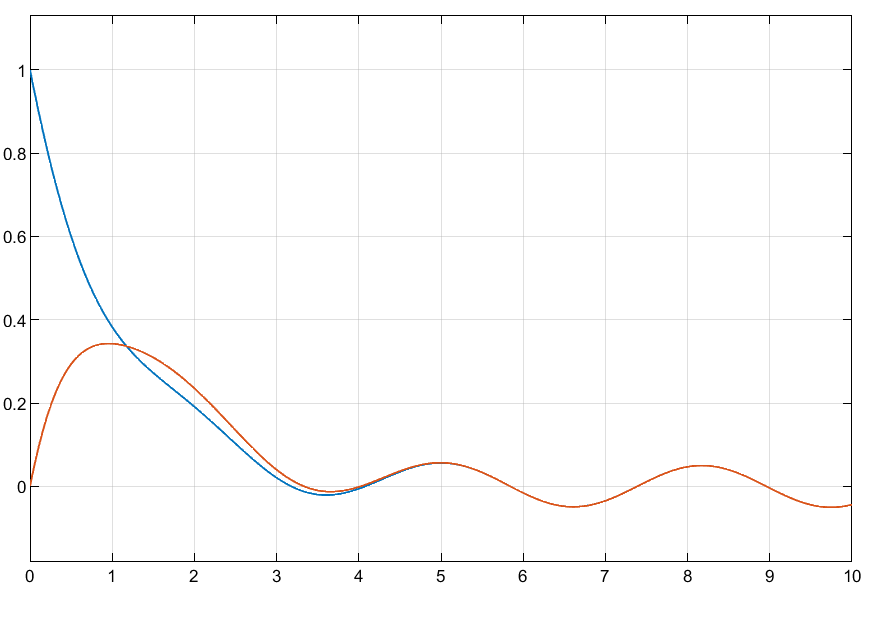

In the first graph, the real plant output are depicted. 

# EKF  - revisit in "stochastic" 

                        
$$\begin{array}{l}
\frac{\mathrm{d}\mathrm{x}}{\mathrm{d}\mathrm{t}}=f{\left(x\right)}+\mathrm{G}\mathrm{w}\mathrm{\ },\mathrm{\ }\mathrm{E}{\left[{\mathrm{w}\mathrm{w}}^{\mathrm{T}} \right]}=W\delta \left(t\right)\\
\mathrm{z}=\mathrm{h}{\left(\mathrm{x}\right)}+v\ ,\ E{\left[vv^T \right]}=V\delta \left(t\right)
\end{array}$$
                              

The EKF is  

                            
$$\left.\frac{\mathrm{d}\hat{x} }{dt}=f\left(\hat{x} \right)+PH^T V^{-1} {\left(z-h\left(\hat{x} \right.\right)}\right)$$
 

and the Riccati equation as 

                          
$$\dot{\ P} =FP+PF^T -PH^T V^{-1} HP+W$$


                            $\mathrm{\ }\mathrm{\ }\mathrm{\ }\mathrm{\ }\mathrm{\ }\mathrm{\ }\mathrm{F}\mathrm{\ }:=\frac{\partial \mathrm{f}}{\partial \mathrm{x}}{\left|\right.}_{x=\hat{x} }$,    $\mathrm{H}\mathrm{\ }:=\frac{\partial \mathrm{h}}{\partial \mathrm{x}}{\left|\right.}_{x=\hat{x} }$                                                            

                            
$$\left.{\hat{x} }_{t_0 } =E{\left[x{\left(t_0 \right)}\right]},\ P{\left(t_0 \right)}=cov\left\lbrack x{\left(t_0 \right)}\right\rbrack$$
  

 Comments:

-in non-linear system the optimal control is difficult

-So in this textbook, the get the unique observer gain, adopt the idea from the extened Kalmn filter. However, in this textbook, Riccati equation is not equivalent to the EKF

   1) the Riccati equarion is non-linear compared to the matrix linear differential equation in EKF.

   2) To solve the Riccati equation, the initial conditions are needed. However, in this book, just assume an identity matrix but in EKF, the $Q,R$ are from the noise intensities.

                                                                -The EnD-